name = "High Resolution Edibility Prediction"

df = "direct_ed_bolete.h5_ed_perform.csv"

aucC =    0.488680585000000


aucD =    0.556150000000000


aucB =    0.351661130000000


aucS =    0.226802000000000


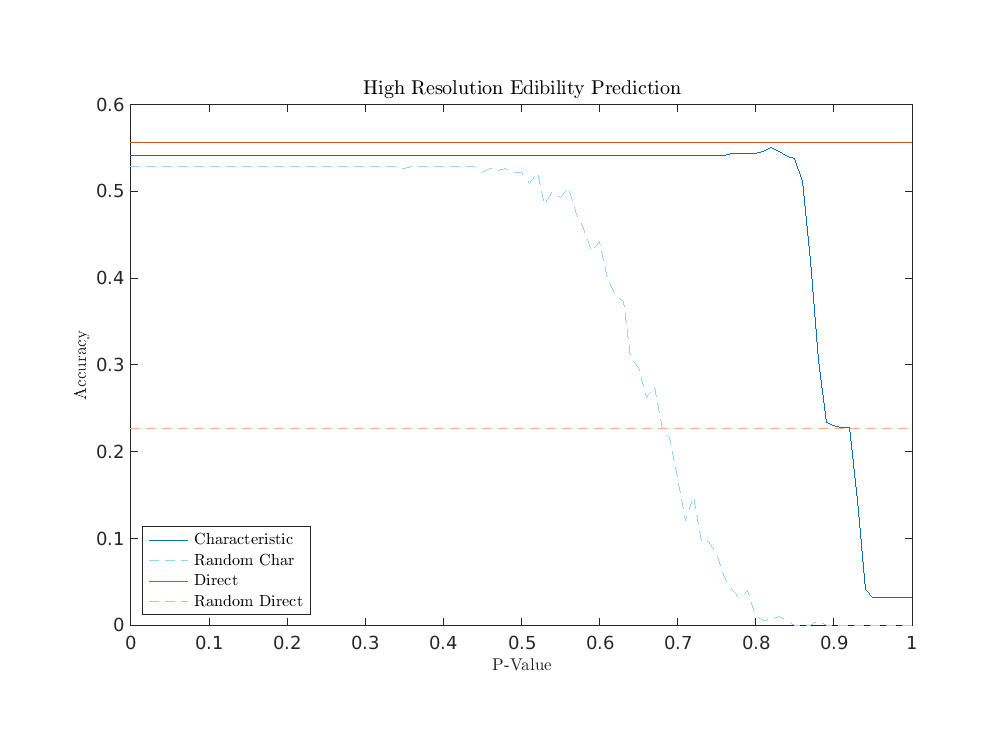

name = "High Resolution Species Prediction"

df = "direct_bolete.h5_perform.csv"

aucC =    0.089489125000000


aucD =    0.236800940000000


aucB =    0.053565250000000


aucS =    0.082363980000000


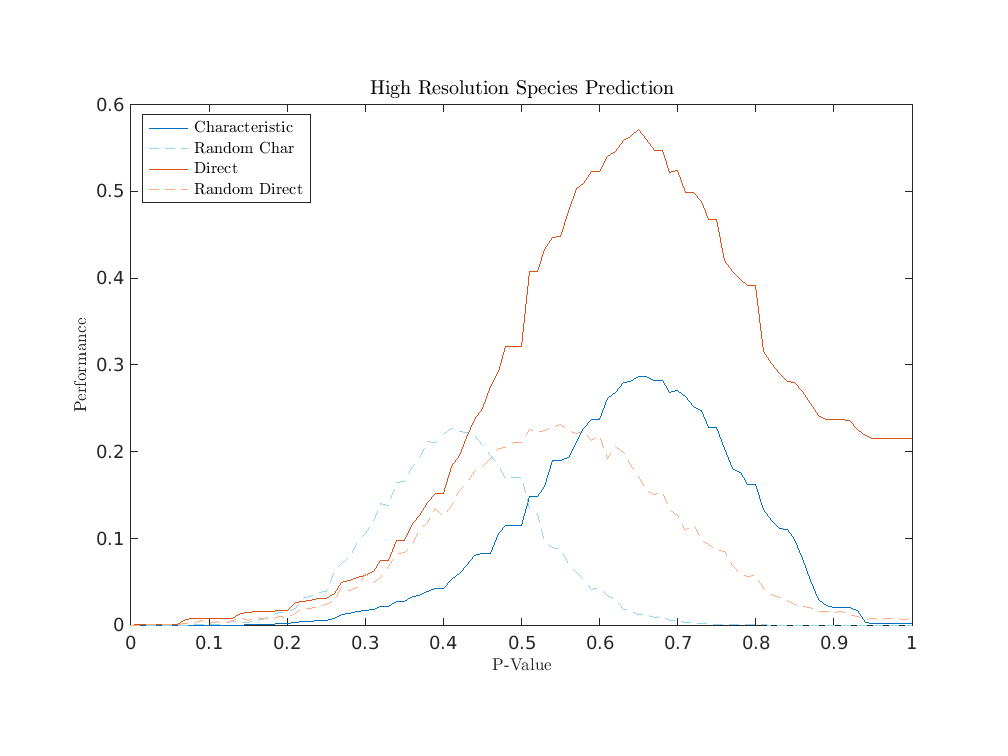

name = "Low Resolution Edibility Prediction"

df = "direct_ed_bolete_lowres.h5_ed_perform.csv"

aucC =    0.489856990000000


aucD =    0.549020000000000


aucB =    0.351661130000000


aucS =    0.226802000000000


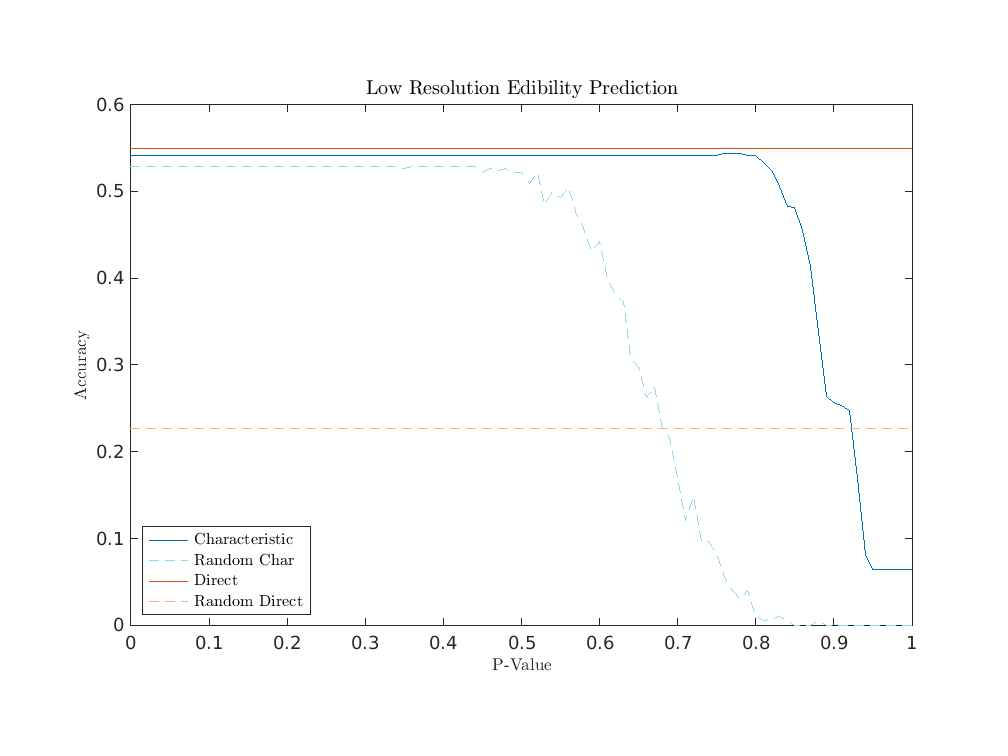

name = "Low Resolution Species Prediction"

df = "direct_bolete_lowres.h5_perform.csv"

aucC =    0.095993010000000


aucD =    0.222766905000000


aucB =    0.053565250000000


aucS =    0.082363980000000


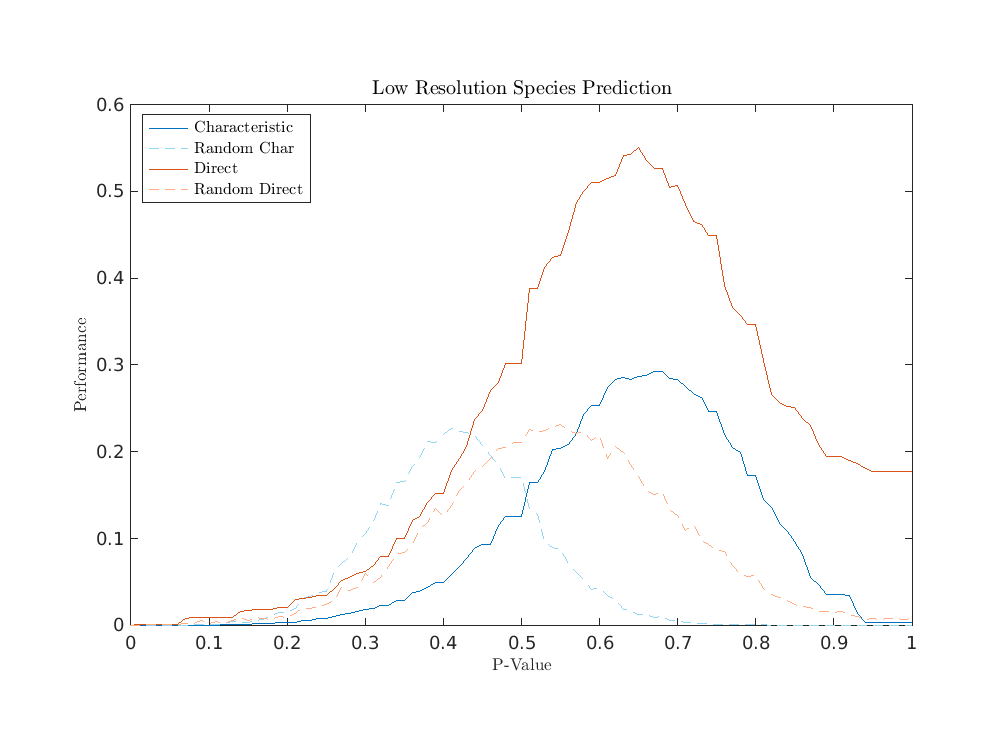

format long
files = dir("performance_data/*_perform.csv");
names = string.empty(length(files), 0);
for i = 1:length(files)
    names(i) = files(i).name;
end
names = names';
cfiles = names(contains(names, "characteristic"));
clen = length('characteristic');
dfiles = names(contains(names, "direct"));
dlen = length('direct');

PRC = readmatrix("performance_data/random_char_perform.csv")';
PCE = readmatrix("performance_data/random_char_ed_perform.csv")';
PRD = readmatrix("performance_data/random_direct_perform.csv")';
PDE = readmatrix("performance_data/random_direct_ed_perform.csv")';
for i= 1:length(cfiles)
    cf = cfiles(i);
    suffix = cf{1}(clen+1:end);
    name = title_from_suffix(suffix)
    if contains(suffix, "ed")
        df = dfiles(dfiles == "direct_ed" +  suffix)
    else
        df = dfiles(dfiles == "direct" +  suffix)
    end
    
    PC = readmatrix("performance_data/" + cf)';
    PD = readmatrix("performance_data/" + df)';
    
    figure
    
    if contains(name, "edibility", "IgnoreCase", true)
    plotP(PC, PD, PCE, PDE, name);
    else
    plotP(PC, PD, PRC, PRD, name);
    end
    title(name,"Interpreter", "latex" ,"FontSize",14)
    saveas(gcf, "plots/" + replace(name, newline, "") + ".png")
end


% SPECIES EXPECTATIONS
PP = readmatrix("performance_data/perfect_perform.csv")';
PD = readmatrix("performance_data/random_direct_perform.csv")';

plot(PRC(:,1), PRC(:,2));
hold on
plot(PD(:,1), PD(:,2));
plot(PP(:,1), PP(:,2));
hold off

aucP = trapz(PP(:,1), PP(:,2))

aucP =    0.454742305000000


aucB = trapz(PRC(:,1), PRC(:,2))

aucB =    0.053565250000000


aucS = trapz(PD(:,1), PD(:,2))

aucS =    0.082363980000000


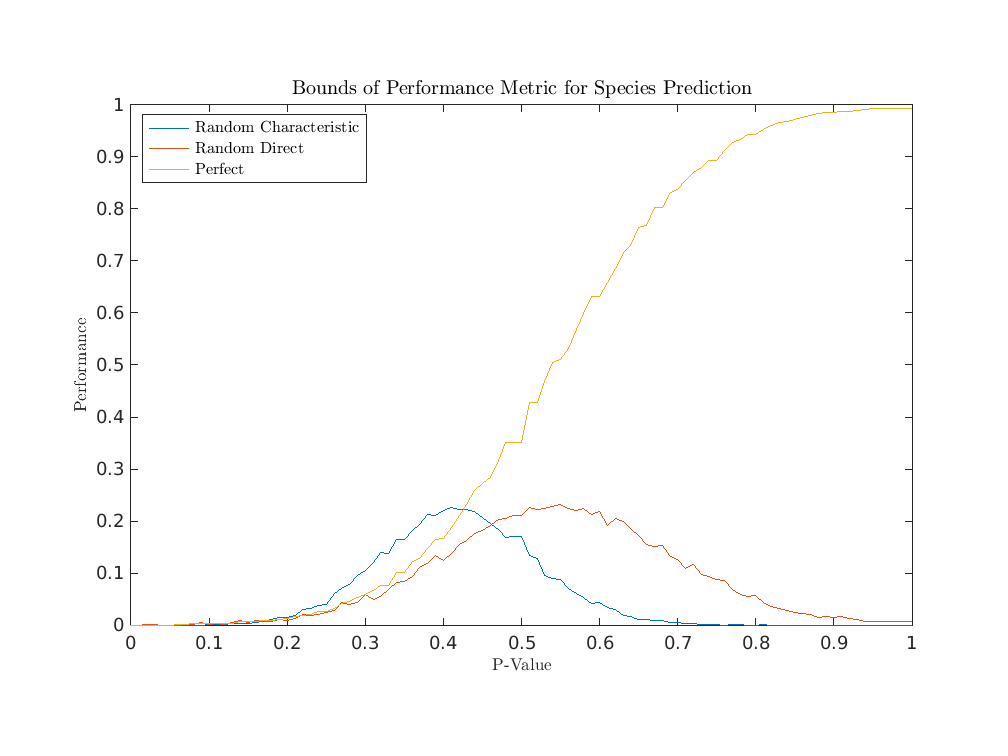


xlabel("P-Value", "Interpreter","latex", "FontSize",13);
ylabel("Performance", "Interpreter","latex", "FontSize",13);
title("Bounds of Performance Metric for Species Prediction", "Interpreter","latex", "FontSize",14);
legend( ...
    "Random Characteristic",...+newline+"AUC="+aucB,...
    "Random Direct",...+newline+"AUC="+aucS,...
    "Perfect",...+newline+"AUC="+aucP,...
    "Location","northwest", "Interpreter","latex");
pbaspect([1.5,1,1])
saveas(gcf, "plots/Perfect Performance.png")



% EDIBILITY EXPECTATIONS
PPE = readmatrix("performance_data/perfect_ed_perform.csv")';
PDE = readmatrix("performance_data/random_direct_ed_perform.csv")';
PCE = readmatrix("performance_data/random_char_ed_perform.csv")';

plot(PCE(:,1), PCE(:,2));
hold on
plot(PDE(:,1), PDE(:,2));
plot(PPE(:,1), PPE(:,2));
% yline(1);
hold off

aucP = trapz(PPE(:,1), PPE(:,2))

aucP =    0.608837330000000


aucB = trapz(PCE(:,1), PCE(:,2))

aucB =    0.351661130000000


aucS = trapz(PDE(:,1), PDE(:,2))

aucS =    0.226802000000000


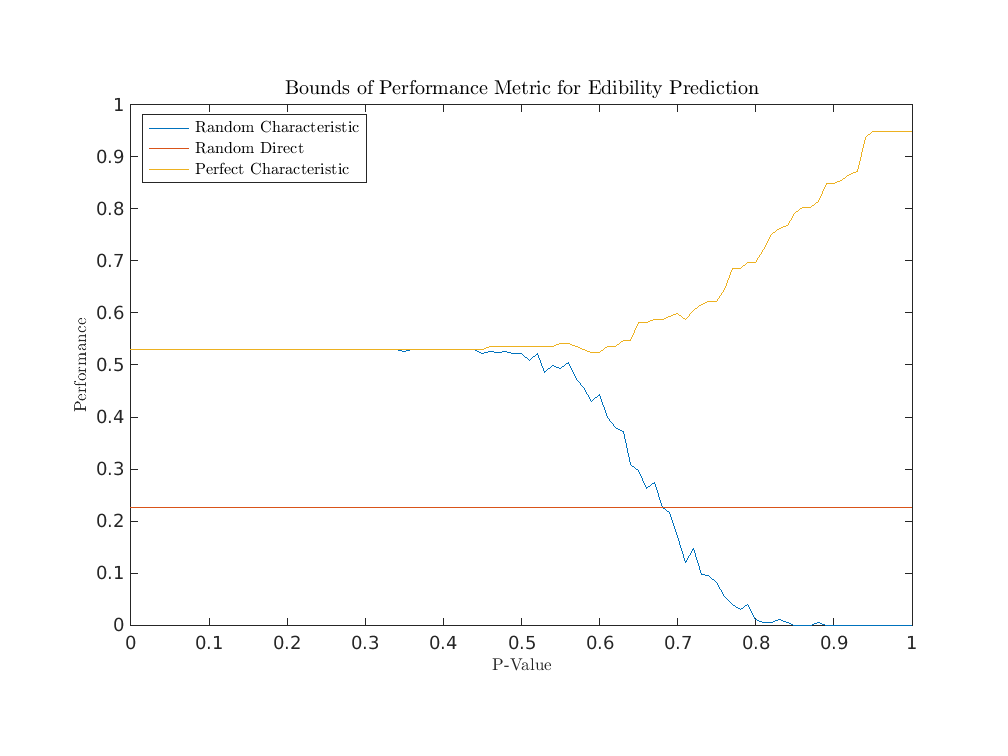


xlabel("P-Value", "Interpreter","latex", "FontSize",13);
ylabel("Performance", "Interpreter","latex", "FontSize",13);
title("Bounds of Performance Metric for Edibility Prediction", "Interpreter","latex", "FontSize",14);
legend( ...
    "Random Characteristic",...+newline+"AUC="+aucB,...
    "Random Direct",...+newline+"AUC="+aucS,...
    "Perfect Characteristic",...+newline+"AUC="+aucP,...
    "Location","northwest", "Interpreter","latex");
pbaspect([1.5,1,1])
saveas(gcf, "plots/Perfect Edibility Performance.png")



% TAU HAT EXPECTATIONS
PH = readmatrix("performance_data/bolete.h5_tau_hat_similarity.csv")';
PL = readmatrix("performance_data/bolete_lowres.h5_tau_hat_similarity.csv")';
plot(PH(:,1), PH(:,2));
hold on
plot(PL(:,1), PL(:,2));
hold off

aucH = trapz(PH(:,1), PH(:,2))

aucH =    0.529400000000000


aucL = trapz(PL(:,1), PL(:,2))

aucL =    0.529950000000000


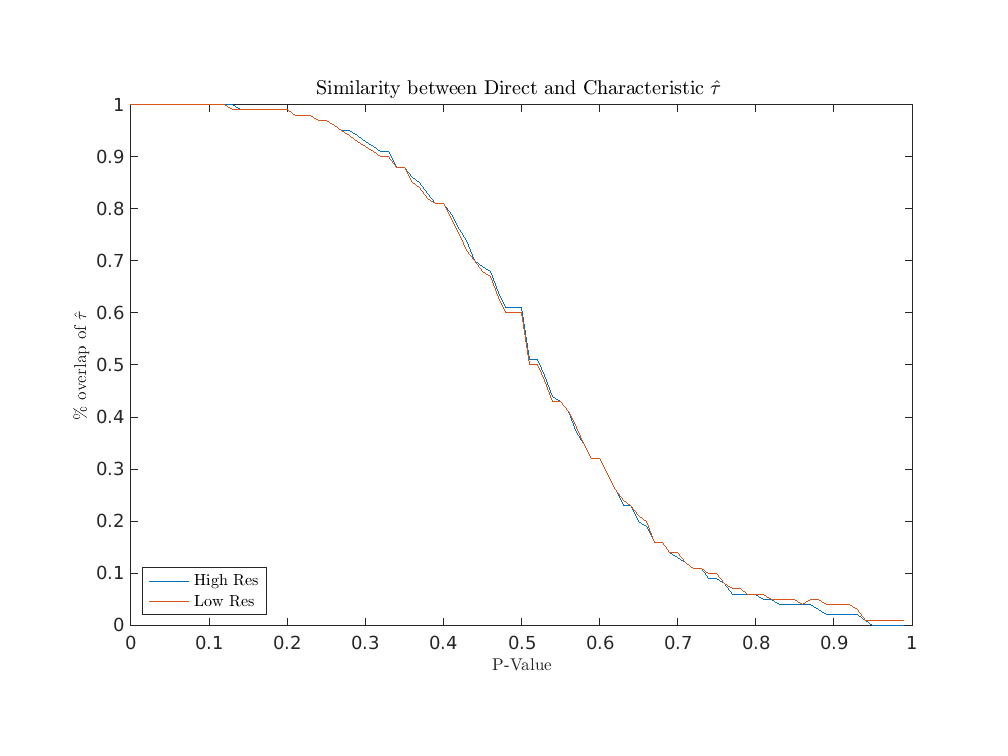


xlabel("P-Value", "Interpreter","latex", "FontSize",13);
ylabel("\% overlap of $\hat{\tau}$", "Interpreter","latex", "FontSize",13);
title("Similarity between Direct and Characteristic $\hat{\tau}$ ", "Interpreter","latex", "FontSize",14);
l = legend("High Res",...
    "Low Res",...
    "Location","southwest", "Interpreter","latex");
pbaspect([1.5,1,1])
saveas(gcf, "plots/TauHat Similarity.png")

function plotP(PC, PD, PB, PS, name)
plot(PC(:,1), PC(:,2), "Color", '#0072BD');
hold on
plot(PB(:,1), PB(:,2), '--', "Color",1-[0.8500 0.3250 0.0980]*.5);

plot(PD(:,1), PD(:,2), "Color", '#D95319');
%     brighten(0.1)
plot(PS(:,1), PS(:,2), '--', "Color",1-[0 0.6470 0.9410]*.5);
hold off
xlabel("P-Value", "Interpreter","latex", "FontSize",13);
if contains(name, "edibility", "IgnoreCase",true)
    ylabel("Accuracy", "Interpreter","latex", "FontSize",13);
else
    ylabel("Performance", "Interpreter","latex", "FontSize",13);
end
aucC = trapz(PC(:,1), PC(:,2))
aucD = trapz(PD(:,1), PD(:,2))
aucB = trapz(PB(:,1), PB(:,2))
aucS = trapz(PS(:,1), PS(:,2))

title(name, "Interpreter","latex");

if contains(name, "edibility", "IgnoreCase",true)
    loc = "southwest";
else
    loc = "northwest";
end

l = legend(["Characteristic",...+newline+"AUC="+aucC, ...
    "Random Char",...+newline+"AUC="+aucB,...
    "Direct",...+newline+"AUC="+aucD,...
    "Random Direct",...+newline+"AUC="+aucS,...
    ], "Location",loc, "Orientation","vertical", "Interpreter","latex");
%     ], "Location","southoutside", "Orientation","horizontal");
        

% l.Units = "pixels";
f = gcf;
a = gca;
a.Units = "pixels";
% f.Position(3) = 600;
% oldheight = f.Position(4);
% f.Position(4) = f.Position(4) + l.Position(4);
% a.Position(4) = oldheight - l.Position(4);
pbaspect([1.5,1,1])
% l.Position(1) = 0.1;
% f.Position(3) = f.Position(3) + l.Position(3);
end
function tit = title_from_suffix(suffix)
tit = "";
suffix = string(suffix);
if contains(suffix, "_bolete.h5")
    tit = tit + "High Resolution";
else
    tit = tit + "Low Resolution";
end
if contains(suffix, "_ed")
    tit = tit + " Edibility Prediction";
else
    tit = tit + " Species Prediction";
end
end